% make vector of stim conditions in order of presentation/trial,
% & list of unique stim params (for looping)
n = 1;
[durOrderedByTrialMeetCriteria,uniqueDurations,conOrderedByTrialMeetCriteria,uniqueContrasts,conAndDurOrderedByTrialMeetCriteria] = getStimParams4loops(n,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria);

%[conOrderedByTrialMeetCriteria,uniqueContrasts,durOrderedByTrialMeetCriteria,uniqueDurations,conAndDurOrderedByTrialMeetCriteria] = getStimParamsNtrialConds(stimDetails,trialCond,idxOnsetsMeetsCriteria);

% in preparation for making pixel wise figures of flurescene at different stim conditions,
% make figure legends
[reigons,cons4Legend,cons4axes,durs4Legend,durs4Axes] = getSubtitleLegendNaxesInfo(uniqueContrasts,uniqueDurations);
reigons

reigons =     'V1'    'LP-HVA'    'LA-HVA'    'MA-HVA'    'control'


cons4Legend

cons4Legend =     '0'    '0.03'    '0.0625'    '0.125'    '0.25'    '0.5'    '1'


durs4Legend

durs4Legend =     '6'


% SELECT RANGE for IMAGESC to SHOW PIX WISE PRE PERI-STIM FRAMES BASELINE
range = input('Fig 1: from 0-1, what range values to use? Enter in bracket form with low & high end values: ') % don't need to save range var out cuz don't need it in following functions/code, just display it 

range =          0    0.0500


colorMapOrNot = input('use colormap jet or no (yes = 1, no = 2)?: ')

colorMapOrNot = 1

% for one session
n = 2 

n = 2


% EXTRACT list of stim params & stim conditions in order of trial 
%[durOrderedByTrialMeetCriteria,uniqueDurations,conOrderedByTrialMeetCriteria,uniqueContrasts,conAndDurOrderedByTrialMeetCriteria] = getStimParams4loops(n,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria);

% EXTRACT PEAK FRAMES BASELINE,and PTSDFOF
nthPTSdfof = groupPTSdfof{1,n};
nthPeakFrameIdx = groupPeakFrameIdx{1,n}; 
nthBaselineIdx = groupBaselineIdx{1,n};

% EXTRACT STIM ONSET FRAME 
nthStimOnsetFrame = groupStimOnsetFrame{1,n};

% EXTRACT BASELINE IDX
nthBaselineIdx = groupBaselineIdx{1,n};

% EXTRACT ONSET DF
nthOnsetDf = groupOnsetDf{1,n};
    

% PIX-WISE PERI STIM, ALL CONDS, BY STATE 

% CHANGE STATE each time
% state comparison
loco_or_pup = 'pup';


if loco_or_pup == 'loc'

    % EXTRACT loRun TRIAL INDICIES
    idxLoBehStateTrials = groupIdxStatTrials{1,n}; 


    % EXTRACT hiRun TRIAL INDICIES
    idxHiBehStateTrials = groupIdxRunTrials{1,n}; 
    
end

if loco_or_pup == 'pup'

    % EXTRACT hiRun TRIAL INDICIES
    idxLoBehStateTrials = groupIdxSmallPupilTrials{1,n}; 
    
    % EXTRACT hiRun TRIAL INDICIES
    idxHiBehStateTrials = groupIdxLargePupilTrials{1,n}; 
    
end


% 7 cons, 1 dur
cont = 1:length(uniqueContrasts); 
durat = 1:length(uniqueDurations); 

numSubtractFramesFromEnd = 6;

% 2 types of frame indicies
f = nthStimOnsetFrame+1:size(nthOnsetDf,3)-numSubtractFramesFromEnd; % stim onset til end of onsetDf segment (need to use size here cuz longest dim is trials, not frames for onsetDf)
numFrames = length(f);


% LO STATE

fig1 = figure

fig1 =   Figure (14) with properties:

      Number: 14
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


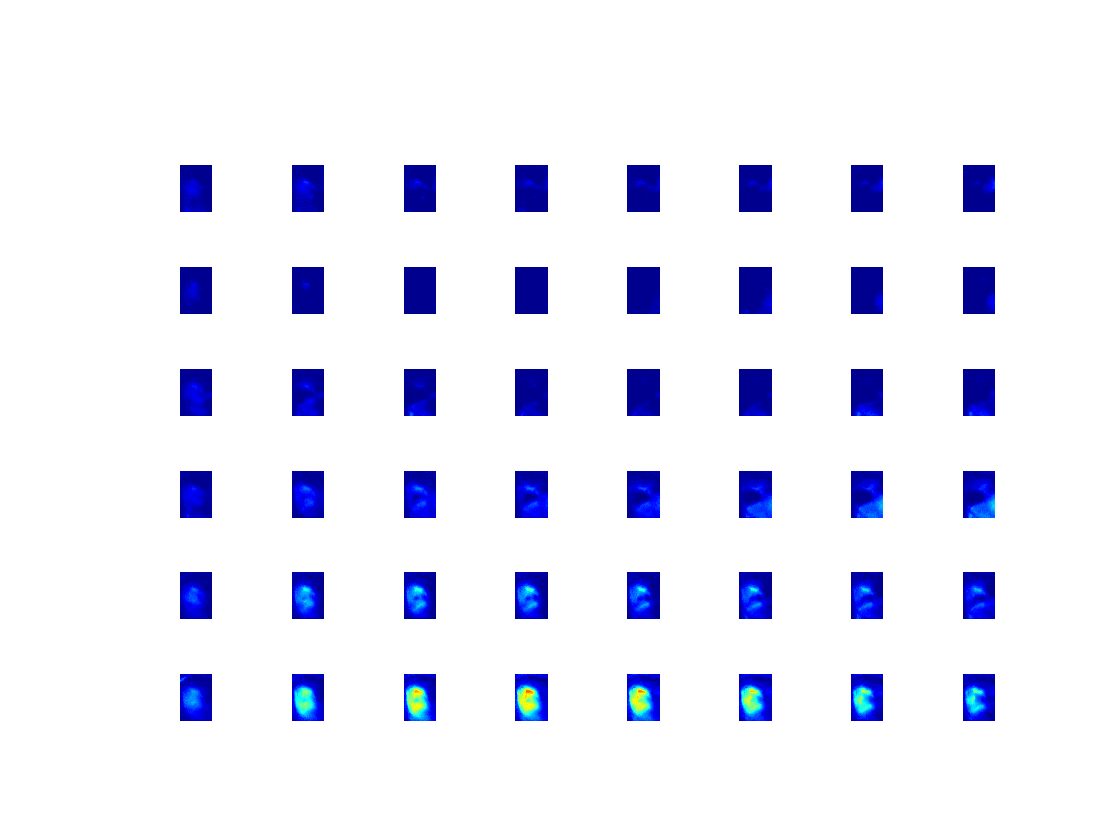


for d = durat % one duration

    for c = cont(2:end) % 7 contrasts
        
        clear behStateTrials
        behStateTrials = idxLoBehStateTrials;

        clear idxTrials
        [idxTrials] = getTrials(conAndDurOrderedByTrialMeetCriteria,c,d,uniqueContrasts,uniqueDurations,behStateTrials);
        
        for nF = 1:numFrames % for each peri-stim frame
            
            % CALCULATE MEAN BASELINE IMAGE (across all frames)
                
            % get baseline frames, across all points, selected trials
            clear allBaselineFrames
            allBaselineFrames = nthOnsetDf(:,:,nthBaselineIdx,idxTrials);
            % take mean over frames for baseline frames of selected trials
            clear meanBaselineFrames
            meanBaselineFrames = mean(allBaselineFrames,3); % 3rd dim is frames
            meanBaselineFrames = squeeze(meanBaselineFrames);
            % average over trials
            clear meanBaselineImage
            meanBaselineImage = mean(meanBaselineFrames,3); % this is the "mean baseline image"
        
            % PLOT baselined pix wise peri stim for each contrast
            
            % index "real frame index ('f') using "index of selelcted frame indicies (nF) from onsetDf"
            % take the idx for f-th frame ('f(nF)'), and when c is greater than one, add multiples of 
            % the number of columns/frames, so that all the rows fill out...
            subplot(length(uniqueContrasts),numFrames,(f(nF)-nthStimOnsetFrame)+(numFrames*(c-1))) % +(length(uniqueContrasts)*(c-1))

            % baseline & plot here
            imagesc(mean(nthOnsetDf(:,:,f(nF),idxTrials),4)-meanBaselineImage,range) % trials defined in 1st step of this code
        
             %title(f);
             
             if colorMapOrNot == 1
                colormap jet
             end 
        
             axis off;
             %axis image;
             
%              fntName = 'SansSerif';
%              fntSize = 10;
%              set(gca, 'FontSize', fntSize, 'FontName', fntName)
             xlabel('frames')
             ylabel('contrast')
             
            end % end frames loop
    
    end % end contrast loop
    
end % end duration loop

fntSize = 10;
fntName = 'SansSerif';
fontMult = 1.5;
set(gca, 'FontSize', fntSize, 'FontName', fntName)

% % Give common xlabel & ylabel
% han=axes(fig1,'visible','off'); 
% han.XLabel.Visible='on';
% han.YLabel.Visible='on';
% ylabel(han,'contrast');
% xlabel(han,'frames');

%print('pixwisePeriStimLoState_loLoco_n1_expt3.png','-dpng')
%print('pixwisePeriStimLoState_loPup_n1_expt3.png','-dpng')



% HI STATE

fig2 = figure

fig2 =   Figure (15) with properties:

      Number: 15
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


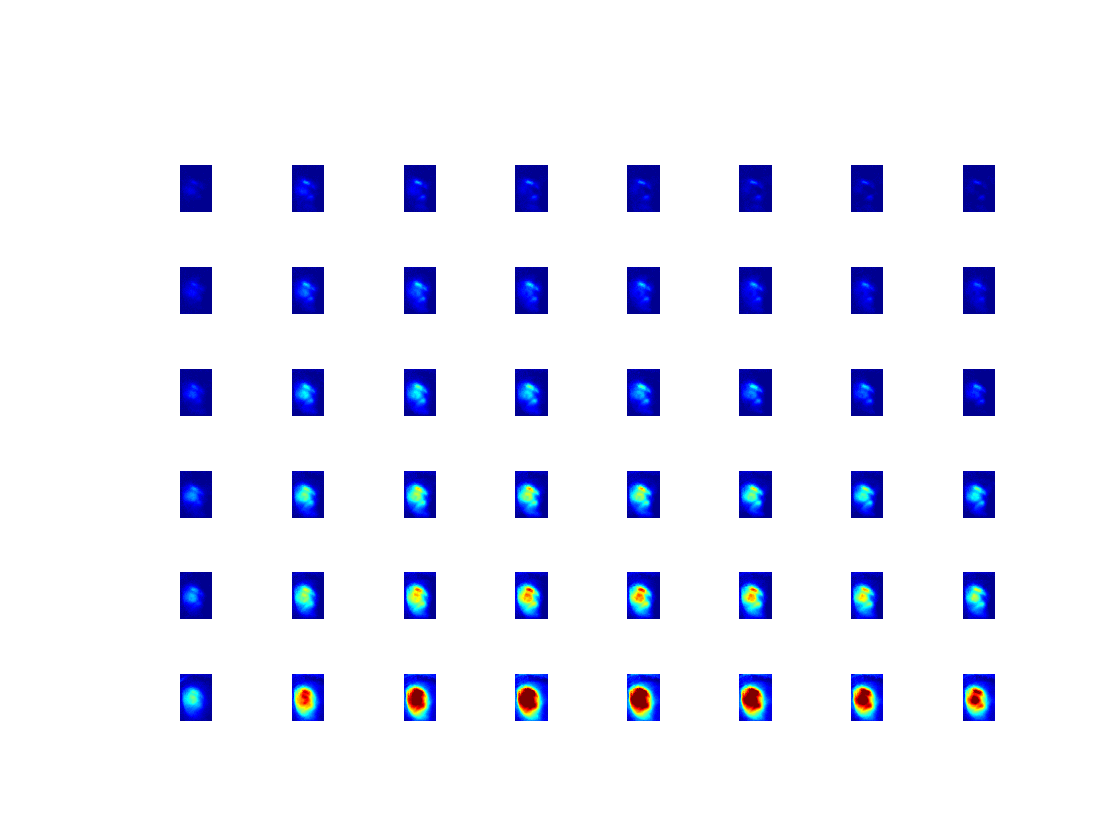


for d = durat % one duration

    for c = cont(2:end) % 7 contrasts
        
        clear behStateTrials
        behStateTrials = idxHiBehStateTrials;

        clear idxTrials
        [idxTrials] = getTrials(conAndDurOrderedByTrialMeetCriteria,c,d,uniqueContrasts,uniqueDurations,behStateTrials);
        
        for nF = 1:numFrames % for each peri-stim frame
            
            % CALCULATE MEAN BASELINE IMAGE (across all frames)
                
            % get baseline frames, across all points, selected trials
            clear allBaselineFrames
            allBaselineFrames = nthOnsetDf(:,:,nthBaselineIdx,idxTrials);
            % take mean over frames for baseline frames of selected trials
            clear meanBaselineFrames
            meanBaselineFrames = mean(allBaselineFrames,3); % 3rd dim is frames
            meanBaselineFrames = squeeze(meanBaselineFrames);
            % average over trials
            clear meanBaselineImage
            meanBaselineImage = mean(meanBaselineFrames,3); % this is the "mean baseline image"
        
            % PLOT baselined pix wise peri stim for each contrast
            
            % index "real frame index ('f') using "index of selelcted frame indicies (nF) from onsetDf"
            % take the idx for f-th frame ('f(nF)'), and when c is greater than one, add multiples of 
            % the number of columns/frames, so that all the rows fill out...
            subplot(length(uniqueContrasts),numFrames,(f(nF)-nthStimOnsetFrame)+(numFrames*(c-1))) % +(length(uniqueContrasts)*(c-1))

            % baseline & plot here
            imagesc(mean(nthOnsetDf(:,:,f(nF),idxTrials),4)-meanBaselineImage,range) % trials defined in 1st step of this code
        
             %title(f);
             
             if colorMapOrNot == 1
                colormap jet
             end 
        
             axis off;
             %axis image;
                      
            end % end frames loop
    
    end % end contrast loop
    
end % end duration loop

fntSize = 10;
fntName = 'SansSerif';
fontMult = 1.5;
set(gca, 'FontSize', fntSize, 'FontName', fntName)

% % Give common xlabel & ylabel
% han=axes(fig,'visible','off'); 
% han.XLabel.Visible='on';
% han.YLabel.Visible='on';
% ylabel(han,'contrast');
% xlabel(han,'frames');

%print('pixwisePeriStimHiState_hiLoco_n1_expt3.png','-dpng')
%print('pixwisePeriStimHiState_hiPup_n1_expt3.png','-dpng')

figure

% % going to show pix wise image for cth contrast (row) at each duration (column)
% for d = 1:length(uniqueDurations)
         
subplot(1,6,1)
imshow('2_Con.png')

subplot(1,6,2)
imshow('3_Con.png')

subplot(1,6,3)
imshow('4_Con.png')

subplot(1,6,4)
imshow('5_Con.png')

subplot(1,6,5)
imshow('6_Con.png')

subplot(1,6,6)
imshow('7_Con.png')

axis off;
axis image;

%print('allStim_expt3.png','-dpng')

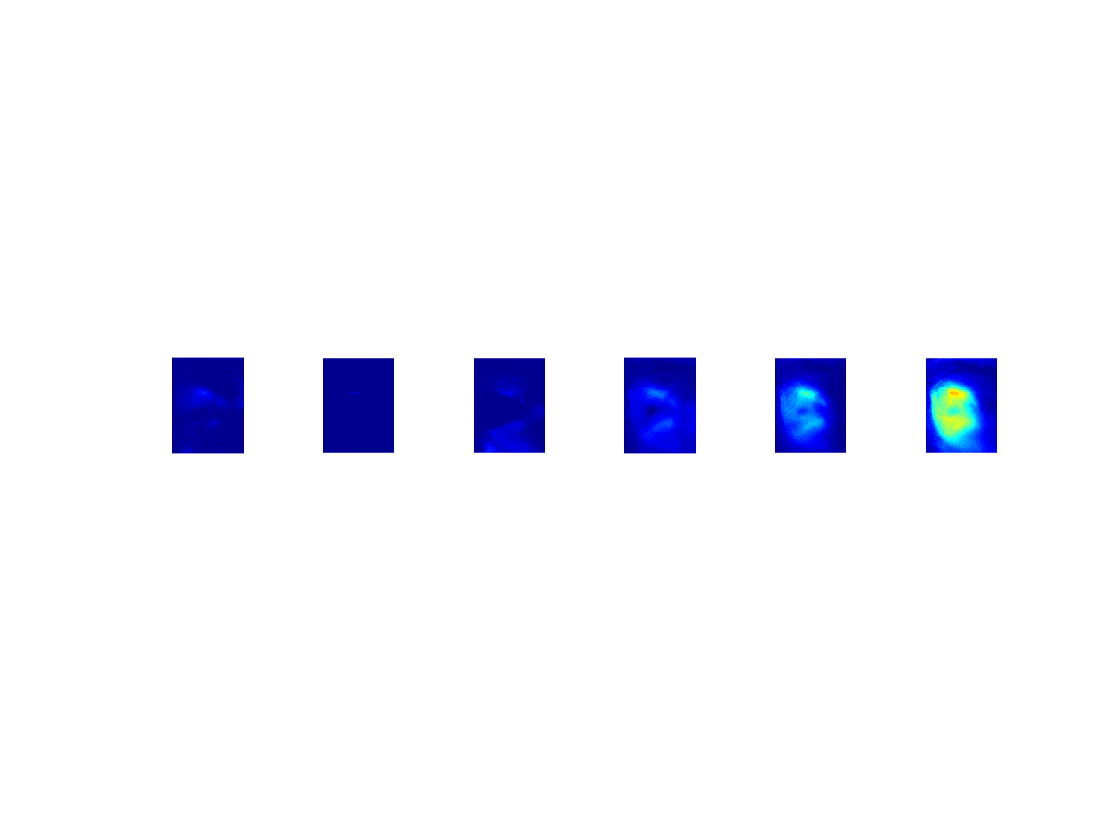

% CHANGE STATE each time
% state comparison
loco_or_pup = 'pup';


if loco_or_pup == 'loc'

    % EXTRACT loRun TRIAL INDICIES
    idxLoBehStateTrials = groupIdxStatTrials{1,n}; 


    % EXTRACT hiRun TRIAL INDICIES
    idxHiBehStateTrials = groupIdxRunTrials{1,n}; 
    
end

if loco_or_pup == 'pup'

    % EXTRACT hiRun TRIAL INDICIES
    idxLoBehStateTrials = groupIdxSmallPupilTrials{1,n}; 
    
    % EXTRACT hiRun TRIAL INDICIES
    idxHiBehStateTrials = groupIdxLargePupilTrials{1,n}; 
    
end



% PLOT LOW STATE PEAK (EXPT 3)
figure

clear behStateTrials
behStateTrials = idxLoBehStateTrials;
        
for c = cont(2:end);
    
     % PLOT BASElined PEAK image

    % select for trials at the cth contrast & dth duration
     clear idxTrials
     [idxTrials] = getTrials(conAndDurOrderedByTrialMeetCriteria,c,d,uniqueContrasts,uniqueDurations,behStateTrials);

     clear cthDthPeakImage
     % get MEAN PEAK activity IMAGE across CTHDTH TRIALS
     allPeakFramesCthDthtrialsOnsetDf = nthOnsetDf(:,:,nthPeakFrameIdx,idxTrials); % index into peak frames & cth dth trials
     mnPeakFramesCthDthtrialsOnsetDf = mean(allPeakFramesCthDthtrialsOnsetDf,3); % mean over peak frames
     mnPeakFramesCthDthtrialsOnsetDf = squeeze(mnPeakFramesCthDthtrialsOnsetDf); % squeeze
     mnPeakFramesMnCthDthtrialsOnsetDf = mean(mnPeakFramesCthDthtrialsOnsetDf,3); % mean over cthdth trials
     meanPeakImageCthDthTrials = squeeze(mnPeakFramesMnCthDthtrialsOnsetDf); % squeeze

     % get BASEline IMAGE at cthdth trials
     allBaseFramesCthDthtrials = nthOnsetDf(:,:,nthBaselineIdx,idxTrials); % index
     meanBaseFramesCthDthtrials = mean(allBaseFramesCthDthtrials,3); % mean over baseline frames
     meanBaseFramesCthDthtrials = squeeze(meanBaseFramesCthDthtrials); % squeeze
     meanBaseFramesCthDthtrials = mean(meanBaseFramesCthDthtrials,3); % mean over trials
     meanBaseImageCthDthtrials = squeeze(meanBaseFramesCthDthtrials); % squeeze

     % SUBTRACT BASELINE from MEAN PEAK ACTIVITY IMAGE for CTHDTH TRIALS
     % just subtracting an image from an image here, not subtracting one baseline value from each cell in a trace
     baselinedPeakImageCthDthTrials = meanPeakImageCthDthTrials-meanBaseImageCthDthtrials;

     subplot(1,6,c-1)
     imagesc(baselinedPeakImageCthDthTrials,range)
                             
     if colorMapOrNot == 1
        colormap jet
     end 

     axis off;
     axis image;

 end % end c loop   

%print('pixwisePeakStimCondByState_loLoco_n1_expt3.png','-dpng')
print('pixwisePeakStimCondByState_loPup_n1_expt3.png','-dpng')

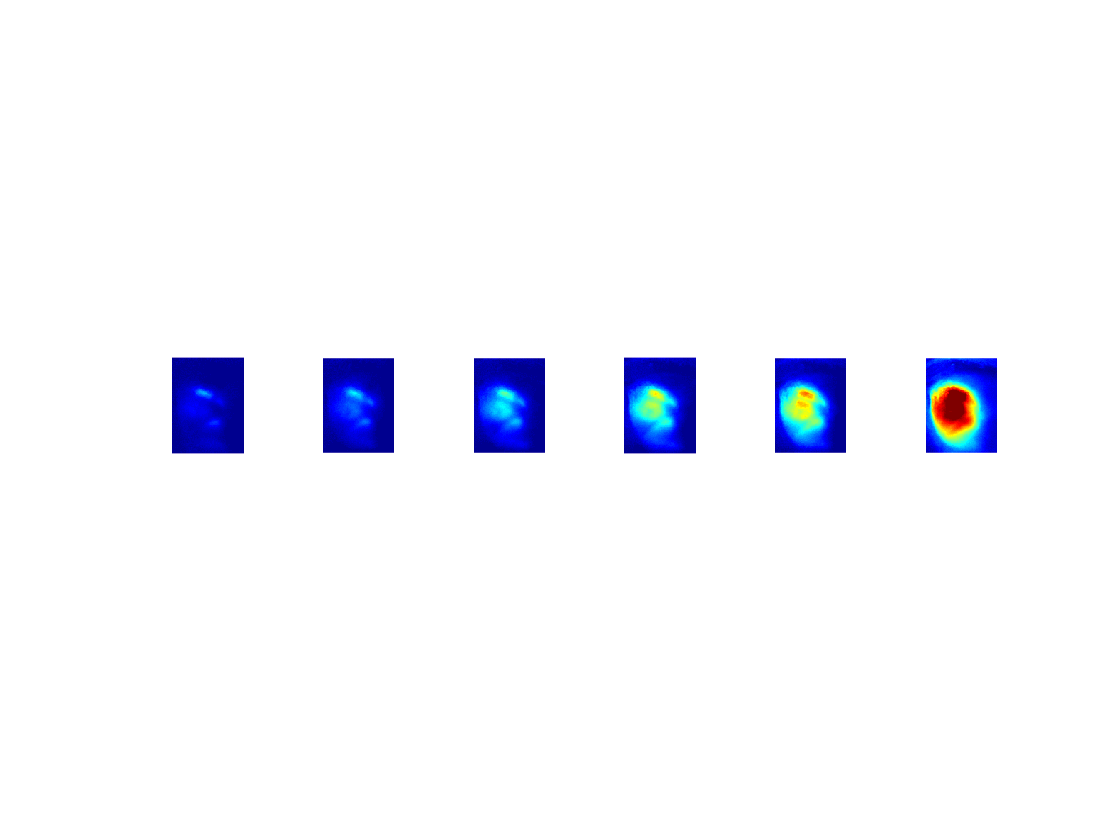


% PLOT HIGH STATE PEAK (EXPT 3)
figure

clear behStateTrials
behStateTrials = idxHiBehStateTrials;
        
for c = cont(2:end);
    
     % PLOT BASElined PEAK image

    % select for trials at the cth contrast & dth duration
    %clear cthDthTrials 
    %cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
    %numCthDthTrials = sum(cthDthTrials)
    
    % same^, but for group
     clear idxTrials
     [idxTrials] = getTrials(conAndDurOrderedByTrialMeetCriteria,c,d,uniqueContrasts,uniqueDurations,behStateTrials);

     % get MEAN PEAK activity IMAGE across CTHDTH TRIALS
     allPeakFramesCthDthtrialsOnsetDf = nthOnsetDf(:,:,nthPeakFrameIdx,idxTrials); % index into peak frames & cth dth trials
     mnPeakFramesCthDthtrialsOnsetDf = mean(allPeakFramesCthDthtrialsOnsetDf,3); % mean over peak frames
     mnPeakFramesCthDthtrialsOnsetDf = squeeze(mnPeakFramesCthDthtrialsOnsetDf); % squeeze
     mnPeakFramesMnCthDthtrialsOnsetDf = mean(mnPeakFramesCthDthtrialsOnsetDf,3); % mean over cthdth trials
     meanPeakImageCthDthTrials = squeeze(mnPeakFramesMnCthDthtrialsOnsetDf); % squeeze

     % get BASEline IMAGE at cthdth trials
     allBaseFramesCthDthtrials = nthOnsetDf(:,:,nthBaselineIdx,idxTrials); % index
     meanBaseFramesCthDthtrials = mean(allBaseFramesCthDthtrials,3); % mean over baseline frames
     meanBaseFramesCthDthtrials = squeeze(meanBaseFramesCthDthtrials); % squeeze
     meanBaseFramesCthDthtrials = mean(meanBaseFramesCthDthtrials,3); % mean over trials
     meanBaseImageCthDthtrials = squeeze(meanBaseFramesCthDthtrials); % squeeze

     % SUBTRACT BASELINE from MEAN PEAK ACTIVITY IMAGE for CTHDTH TRIALS
     % just subtracting an image from an image here, not subtracting one baseline value from each cell in a trace
     baselinedPeakImageCthDthTrials = meanPeakImageCthDthTrials-meanBaseImageCthDthtrials;

     subplot(1,6,c-1)
     imagesc(baselinedPeakImageCthDthTrials,range)
                             
     if colorMapOrNot == 1
        colormap jet
     end 

     axis off;
     axis image;

 end % end c loop   

%print('pixwisePeakStimCondByState_hiLoco_n1_expt3.png','-dpng')
print('pixwisePeakStimCondByState_hiPup_n1_expt3.png','-dpng')